# Spot diagram

An *aberration* is a property of an optical system that causes light to fail to converge on a single point. The optical system of a model eye is subject to aberrations, as is the biological eye.

One way to characterize the aberration in an optical system is with a spot diagram. A set of rays from a point in object space are directed so that they evenly fill the entrance window. If the optical system was free of aberrations, then these rays should all converge at a single point on the retina. A plot of the dispersion of these points in space is a spot diagram.

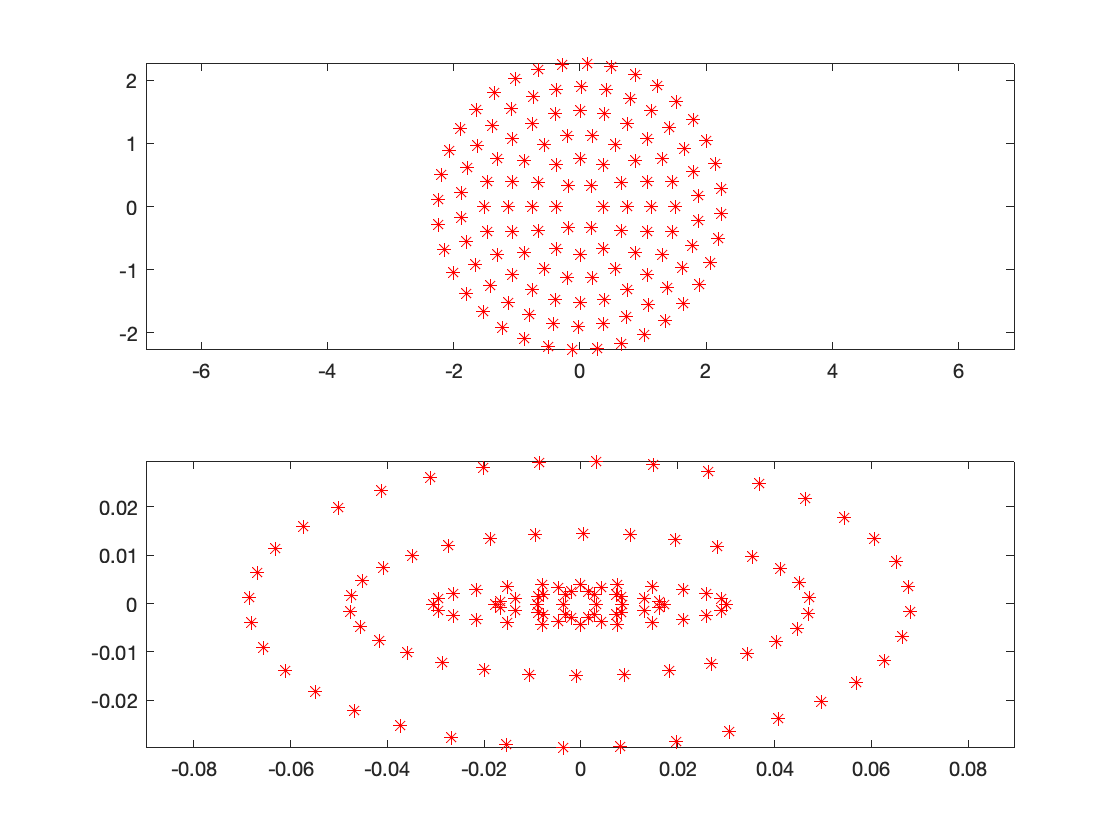

accommodation = 1;
stopRadius = 2;
eye = modelEyeParameters('spectralDomain','vis','accommodation',accommodation);
% Pick a field location
rayOriginDistance = 1000/accommodation;
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);
fieldAngularPosition = [0 0];

% Loop over radii
nRings = 6;
scale = linspace(0,1,nRings+1);
scale = scale(2:end);
retinaPoints = [];
rayPaths = {};
for rr = 1:nRings
    nStopPerimPoints = round(36 .* scale(rr));
    thisRadius = stopRadius * scale(rr);
    [tempPoints,tempPaths] = calcRayBundleFromField(eye,fieldAngularPosition,thisRadius,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord,nStopPerimPoints);
    retinaPoints = [retinaPoints, tempPoints];
    rayPaths = [rayPaths, tempPaths];
end

% Extract the ray positions as they intersect the cornea
corneaPoints = cell2mat(cellfun(@(x) x(:,2),rayPaths,'UniformOutput',false));

% Plot the spot diagram
figure;
subplot(2,1,1); plot(corneaPoints(2,:),corneaPoints(3,:),'*r'); axis equal
subplot(2,1,2); plot(retinaPoints(2,:),retinaPoints(3,:),'*r'); axis equal

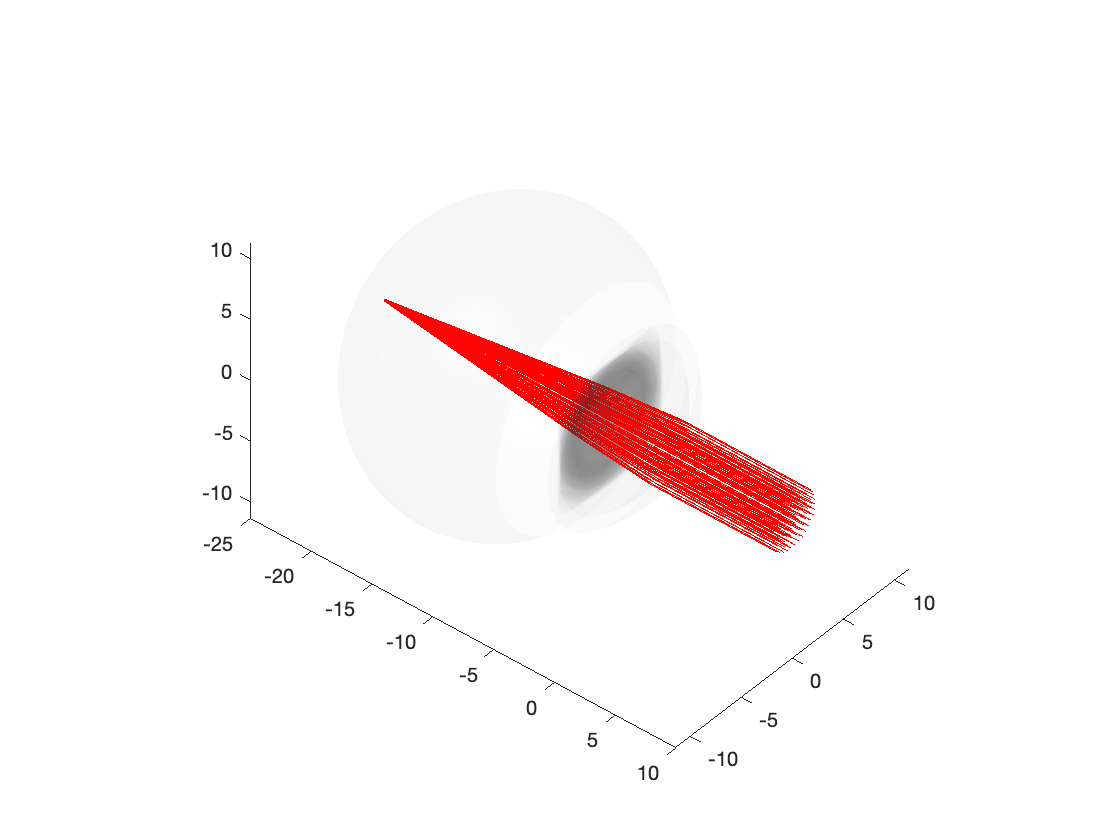


% Plot the optical system
opticalSystem = assembleOpticalSystem(eye,'surfaceSetName','mediumToRetina');
figure
plotOpticalSystem('newFigure',false,'surfaceSet',opticalSystem,'addLighting',true,'surfaceAlpha', 0.05);
% Add the rays to the plot
for ii=1:length(rayPaths)
    plotOpticalSystem('newFigure',false,'rayPath',rayPaths{ii});
end
xlim([-25 10]);